# Weekly Gasoline Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

The file `weeklyGasPrices.csv` contains the average price of gas in 7 different countries for each week between 1996 and 2005.

gas = readtable("./data/weeklyGasPrices.csv");

## Task 2

gas = gas(1:91, :);

## Task 3

The first column of `gas` contains the dates of the recorded gas prices. The remaining columns of the table each correspond to one country. The first 6 countries are in Europe, and the last country is the US.

gas.EuroAvg = mean(gas{:, 2:7}, 2);

## Task 4

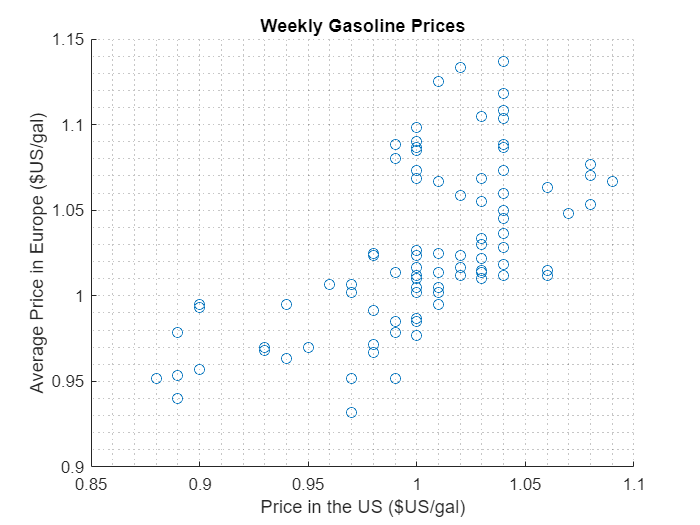

scatter(gas.US, gas.EuroAvg)
xlabel("Price in the US ($US/gal)")
ylabel("Average Price in Europe ($US/gal)")
title("Weekly Gasoline Prices")
grid minor